clear; close all;
d_ss=.038; sig_ih=0.023; sig_h=0.030

sig_h = 0.0300

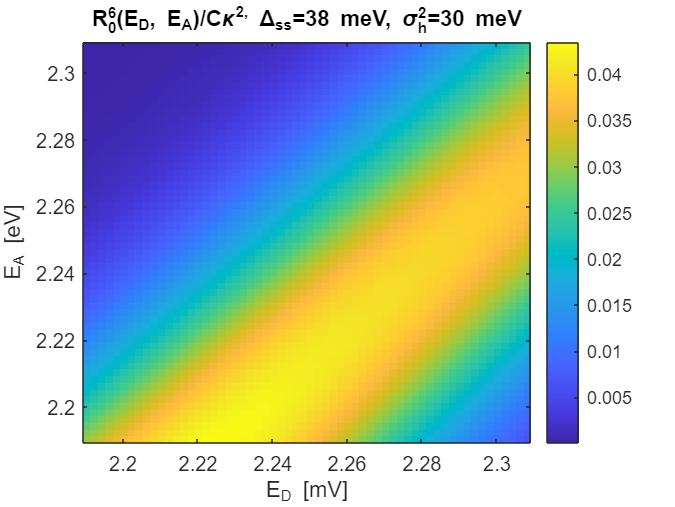

E0=2.25; dE=.002;
E_range=(E0-.023*2.6):dE:(E0+.023*2.6);
%E_range=(2.13):dE:(2.38);
[Ed,Ea] = meshgrid(E_range,E_range);
R0=((.5*(Ed+Ea-d_ss)).^-4).*exp(-((Ed-Ea-d_ss).^2)/(4*sig_h^2));
imagesc(E_range,E_range,R0); colorbar();
set(gca,'YDir','normal');
ylabel("E_A [eV]");xlabel("E_D [mV]");
title("R_0^{6}(E_{D}, E_{A})/C\kappa^2, \Delta_{ss}=38 meV, \sigma_{h}^{2}=30 meV");

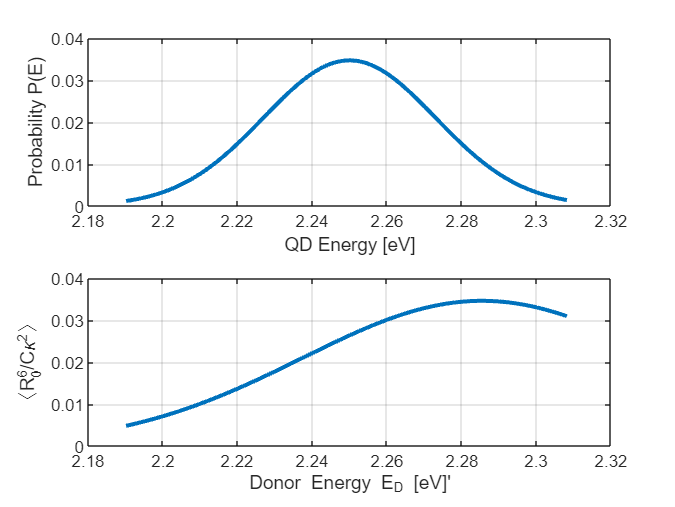

figure();
PE=(1/(sig_ih*sqrt(2*pi)))*exp(-(E_range-E0).^2/(2*sig_ih^2))*dE;
%PE=PE;
PE_sum=sum(PE);
subplot(2,1,1);
plot(E_range,PE,LineWidth=2); grid on;
xlabel("QD Energy [eV]"); ylabel("Probability P(E)")
arr=zeros([length(E_range),1]);
%set(gcf,'position',[0,0,1000,200]);
for i=1:length(E_range)
    avg=PE*R0(:,i)/PE_sum;
    arr(i)=avg;
end
subplot(2,1,2);
plot(E_range,arr,LineWidth=2);grid on;
xlabel("Donor Energy E_{D} [eV]'"); 
ylabel("〈R_{0}^{6}/C\kappa^{2}〉")

Test

close all
dk=.0000002;
kr=0.00000001:dk:.004

kr =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



E_k1=@(E_D)E_D-d_ss+sqrt(-4*(sig_h^2)*log(kr*(2*E_D-2*d_ss)^4));
E_k2=@(E_D)E_D-d_ss-sqrt(-4*(sig_h^2)*log(kr*(2*E_D-2*d_ss)^4));
a=@(E_D)real((1/(sig_ih*sqrt(2*pi)))*exp(-(1/(2*sig_ih^2))*(E_k1(E_D)-E0).^2));
b=@(E_D)real((1/(sig_ih*sqrt(2*pi)))*exp(-(1/(2*sig_ih^2))*(E_k2(E_D)-E0).^2));

n_E=80;
pmat=zeros([n_E,length(kr)]);
edm=linspace(2.14,2.37,n_E)

edm =     2.1400    2.1429    2.1458    2.1487    2.1516    2.1546    2.1575    2.1604    2.1633    2.1662    2.1691    2.1720    2.1749    2.1778    2.1808    2.1837    2.1866    2.1895    2.1924    2.1953    2.1982    2.2011    2.2041    2.2070    2.2099    2.2128    2.2157    2.2186    2.2215    2.2244    2.2273    2.2303    2.2332    2.2361    2.2390    2.2419    2.2448    2.2477    2.2506    2.2535    2.2565    2.2594    2.2623    2.2652    2.2681    2.2710    2.2739    2.2768    2.2797    2.2827


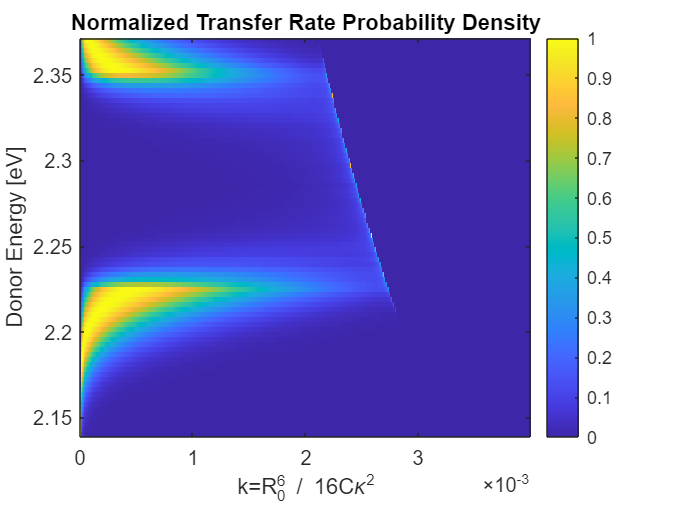

for i=1:n_E
    ed=edm(i);
    a1=a(ed); b1=b(ed);
    %idx = find(((abs(a1-b1))<.000001, 1);
    idx = find((abs(kr-1/(2*ed-2*d_ss)^4))<dk, 1);
    prob_ed=abs((-4*(sig_h^2))*(a1+b1)./(2*kr.*sqrt(-4*(sig_h^2).*log(kr*(2*ed-2*d_ss)^4))));
    prob_ed(idx-1:end)=0;
    pmat(i,:)=prob_ed./max(prob_ed);
end
imagesc(kr,edm,pmat);colorbar();
xlabel("k=R_{0}^{6} / 16C\kappa^{2}");
ylabel("Donor Energy [eV]");
title("Normalized Transfer Rate Probability Density")
clim([0,1])
set(gca,'YDir','normal');

load("kappa.mat");
fkap=@(k)(k<4).*interp1(centers,pmf,k,'spline');
dR=.000001;
Rr=0.00000001:dR:.01;
%n_E2=50; 
n_R=length(Rr);
pmat2=zeros([n_E,length(Rr)]);
edm2=edm;
fkmat=zeros([length(Rr),length(kr)]);
for j=1:n_R
    rd=(Rr(j));
    fkmat(j,:)=fkap(rd./kr);
end

for i=1:n_E
    fk=pmat(i,:)./kr;
    for j=1:n_R
        pmat2(i,j)=sum(fk.*fkmat(j,:))*dR;
    end
    pmat2(i,:)=pmat2(i,:)./(sum(pmat2(i,:)));
end

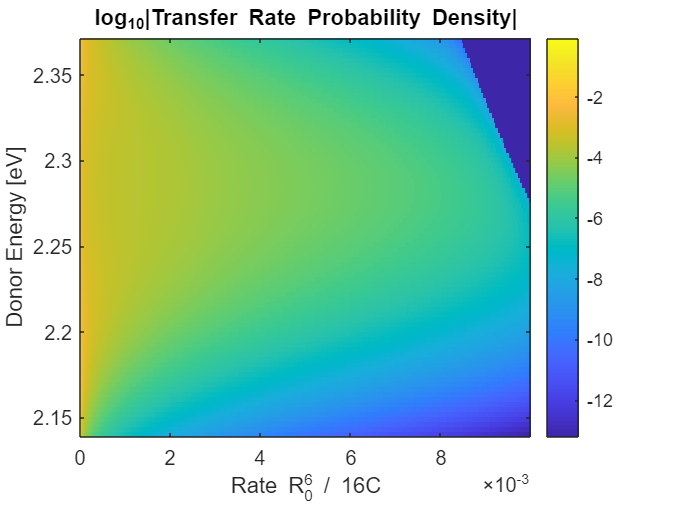


figure();
imagesc(Rr,edm2,log10(pmat2));colorbar();
xlabel("Rate R_{0}^{6} / 16C");
ylabel("Donor Energy [eV]");
title("log_{10}|Transfer Rate Probability Density|")
set(gca,'YDir','normal');

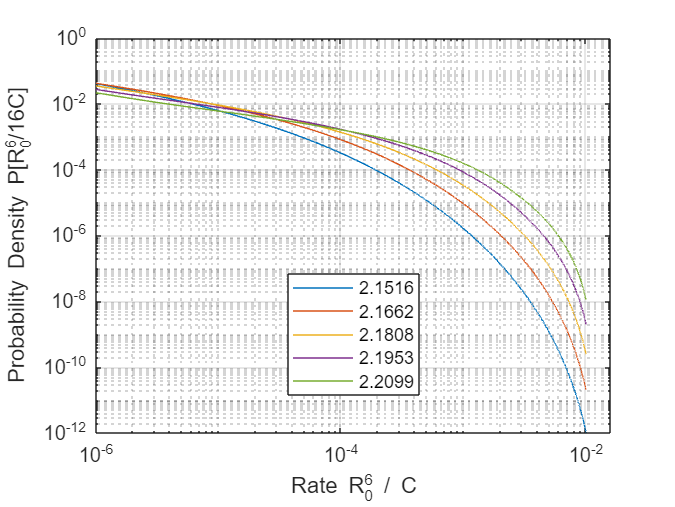


figure();
loglog(Rr,(pmat2(5,:))); hold on;
loglog(Rr,(pmat2(10,:))); hold on;
loglog(Rr,(pmat2(15,:))); hold on;
loglog(Rr,(pmat2(20,:))); hold on;
loglog(Rr,(pmat2(25,:))); hold on;
xlabel("Rate R_{0}^{6} / C");
ylabel("Probability Density P[R_{0}^{6}/16C]");
xlim([1e-6,.016]); grid on;
legend(string(edm2(5)),string(edm2(10)),string(edm2(15)),string(edm2(20)),string(edm2(25)),Location="best")

means

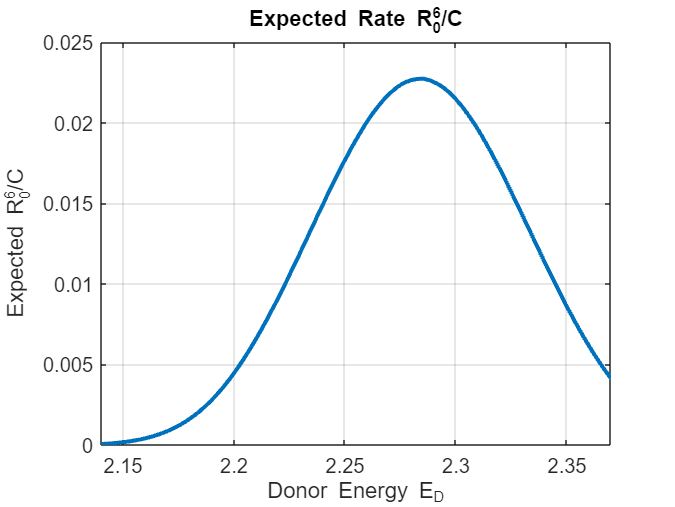

avg_k=sum(pmat2.*Rr,2)./sum(pmat2,2);
figure();
plot(edm2,16*avg_k,LineWidth=2);
ylabel("Expected R_{0}^{6}/C");
xlim([2.14,2.37]); grid on;
xlabel("Donor Energy E_D")
title("Expected Rate R_{0}^{6}/C")

cdf

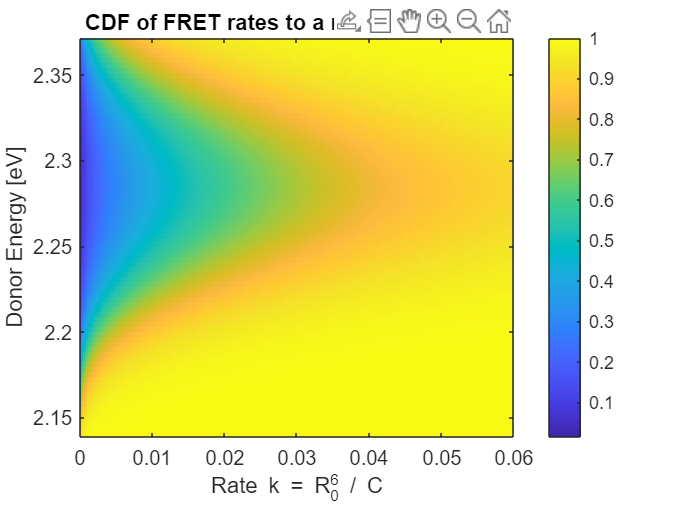


cdf_mat=cumsum(pmat2,2);
imagesc(Rr*16,edm2,cdf_mat);colorbar();
xlabel("Rate k = R_{0}^{6} / C");
ylabel("Donor Energy [eV]");
title("CDF of FRET rates to a random acceptor")
set(gca,'YDir','normal');
xlim(1e-2*[0,6])

%{
ed=2.1+.05;
prob=@(E_D)abs((-4*(sig_h^2))*(a(E_D)+b(E_D))./(2*kr.*sqrt(-4*(sig_h^2).*log(kr*(2*E_D-2*d_ss)^4))))

idx = @(E_D)find((kr > .002) & (abs(a(E_D)-b(E_D)))<.001, 1);
figure();
plot(kr,a(ed)); hold on; grid on;
plot(kr,b(ed));
xlim([0,kr(idx(ed))])
idx_ed=idx(ed);
prob_ed=prob(ed); 
avgtest=prob_ed(1:idx_ed).*dk.*kr(1:idx_ed);
sumtest=prob_ed(1:idx_ed); 
sumtest=sum(sumtest)*dk;
avgtest=sum(avgtest);
disp(sumtest)
disp(avgtest)
figure();
plot(kr,prob(ed));
xlim([0,kr(idx(ed))])
%}
